Read Image

image = imread('test2.jpg');

Converting to Grayscale

inputimage = rgb2gray(image);

Generating the edge image

edge_image = edge(inputimage,'canny');

Display the original image

% imagesc(image)

Parameterization

theta_sample_frequency = 0.01;
[x,y] = size(edge_image);
rho_limit = norm([x y]);
rho = (-rho_limit:1:rho_limit);
theta = (0:theta_sample_frequency:pi);
num_thetas = numel(theta);
num_rhos = numel(rho);
acc = zeros(num_rhos,num_thetas);

Perform Hough Transform

for xi = 1:x
    for yj = 1:y
        if edge_image(xi,yj) == 1
            for theta_id = 1:num_thetas
                th = theta(theta_id);
                r = xi*cos(th) + yj*sin(th);
                rho_id = round(r + num_rhos/2);
                acc(rho_id,theta_id) = acc(rho_id,theta_id) + 1;
            end
        end
    end
end

Show Hough Transform

figure;
imagesc(theta,rho,acc);
title('Hough Transform');
xlabel('Theta (radians)');
ylabel('Rho (pixels)');
colormap("gray");
hold on;

Extract the parameters

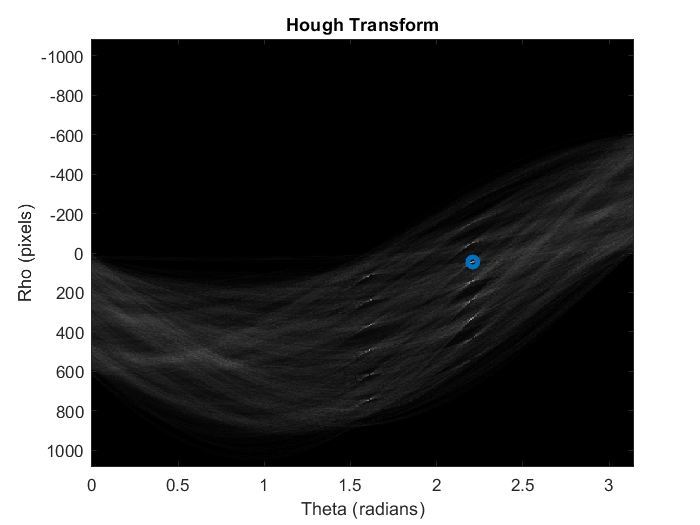

[M,I] = max(acc(:));
[rho_id,theta_id] = ind2sub(size(acc),I);
plot(theta(theta_id),rho(rho_id),'o',"LineWidth",3);
hold off;

Compute the line coordinates

theta_max = theta(theta_id);
rho_max = rho(rho_id);
m = -(cos(theta_max)/sin(theta_max));
b = rho_max / sin(theta_max);
x = 1:x;
y = m*x + b;

Plot the detected line superimposed on original

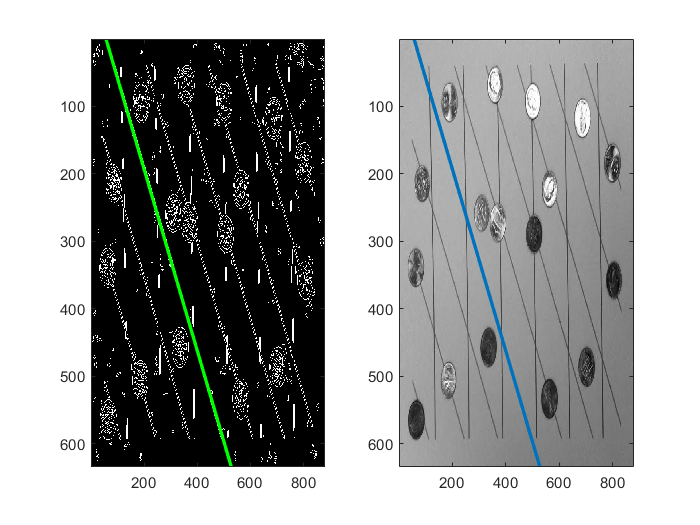

figure;
subplot(1,2,1)
imagesc(edge_image);
colormap('gray');
hold on;
plot(y,x,'g','LineWidth',2)
subplot(1,2,2)
imagesc(inputimage)
colormap('gray')
hold on;
plot(y,x,"LineWidth",2);